MIE301 Mechanism analysis

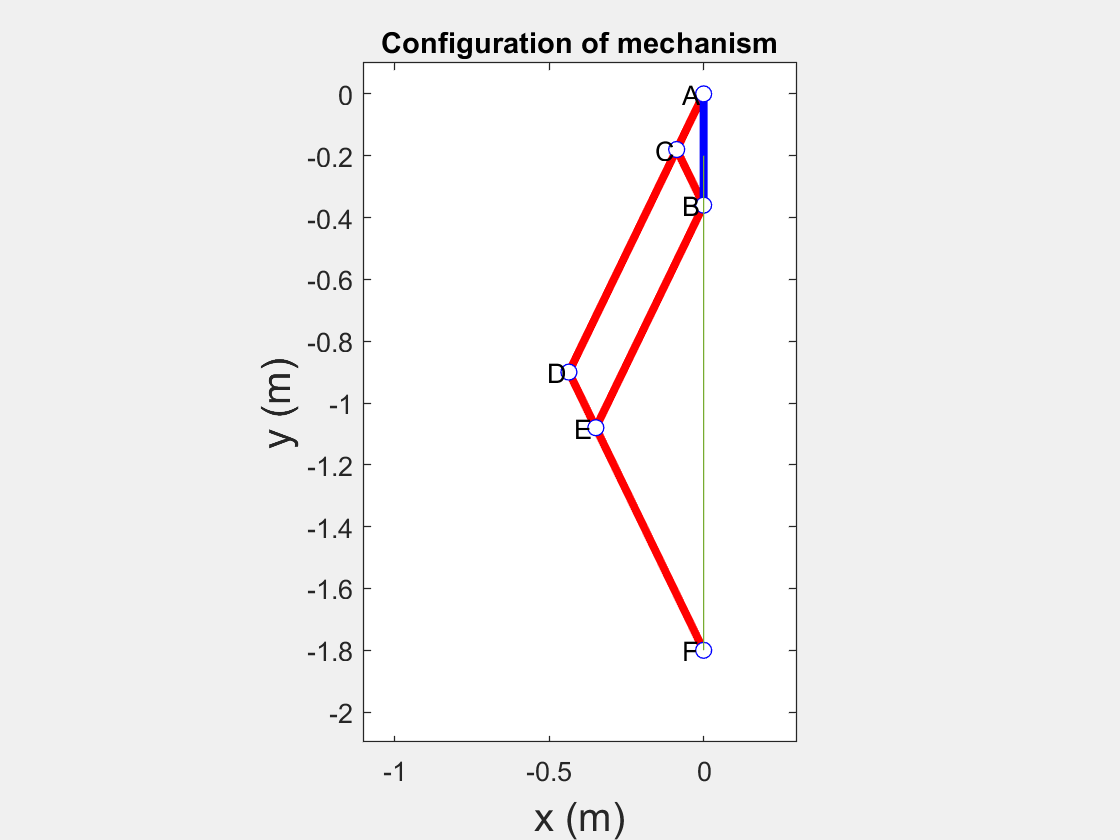

close all; % closes all figures
clear all; % clears all variables from memory
clc;       % clears all calculations from the Matlab workspace

% Plot Parameters: these will be used to set the axis limits on the figure
% (units: 'm')
xmin= -1.1; % leftmost window edge
xmax= 0.3;  % rightmost window edge
ymin= -2.1; % bottom window edge
ymax= 0.1;  % top window edge

% Define the length of the link
r2 = 1;
r3 = 0.2; % Ajust this value to change the mechanism configuration
r4 = r2;
r5 = r2 - r3;

DC = r5;
DE = r3;

steps = 100; % Define the number of steps
acc_ini = 0.1*2*r3; % Define the initial position of the accuator
acc_fin = 0.9*2*r3; % Define the final position of the accuater
accuator = linspace(acc_ini,acc_fin,steps); % Define the step function of the accuator

% set up figure 1
figure(1);                       %create new figure
set(1,'WindowStyle','modal')    %dock the figure

for i = 1:steps
    hold off
    
    % point A on the origion and does not move
    Ax(i) = 0;
    Ay(i) = 0;

    % Point B Driven irectly down by the accuator
    Bx(i) = 0;
    By(i) = -accuator(i);

    % Use cosine law to calculate theta 3
    theta3(i) = acos(((r3^2)+(accuator(i)^2)-(r2-DC)^2)/(2*r3*accuator(i))) + pi/2;
    theta2(i) = acos(-r3*cos(theta3(i))/(r2-DC)); % Calculate theta 2

    Cx(i) = -(r2-DC)*cos(theta2(i));
    Cy(i) = -(r2-DC)*sin(theta2(i));

    Dx(i) = -r2*cos(theta2(i));
    Dy(i) = -r2*sin(theta2(i));

    % theta4(i) = theta3(i);
    % theat5(i) = theat2(i);
    Ex(i) = Dx(i) - DE*cos(theta3(i));
    Ey(i) = Dy(i) - DE*sin(theta3(i));

    Fx(i) = Dx(i) - r4*cos(theta3(i));
    Fy(i) = Dy(i) - r4*sin(theta3(i));
    
    if true % If true, Draw the mechanism on the graph
        % Draw the links
        plot([Ax(i),Dx(i)],[Ay(i),Dy(i)],'Color','r','LineWidth',3);
        hold on
        plot([Cx(i),Bx(i)],[Cy(i),By(i)],'Color','r','LineWidth',3);
        plot([Ax(i),Bx(i)],[Ay(i),By(i)],'Color','b','LineWidth',3);
        plot([Dx(i),Fx(i)],[Dy(i),Fy(i)],'Color','r','LineWidth',3);
        plot([Bx(i),Ex(i)],[By(i),Ey(i)],'Color','r','LineWidth',3);

        % Draw the points
        plot(Ax(i),Ay(i),'bo','MarkerFaceColor','w')
        plot(Bx(i),By(i),'bo','MarkerFaceColor','w')
        plot(Cx(i),Cy(i),'bo','MarkerFaceColor','w')
        plot(Dx(i),Dy(i),'bo','MarkerFaceColor','w')
        plot(Ex(i),Ey(i),'bo','MarkerFaceColor','w')
        plot(Fx(i),Fy(i),'bo','MarkerFaceColor','w')

        % Label the points
        text(Ax(i)-.07, Ay(i), 'A','color','k');       % label point A
        text(Bx(i)-.07, By(i), 'B','color','k');       % label point B
        text(Cx(i)-.07, Cy(i), 'C','color','k');       % label point C
        text(Dx(i)-.07, Dy(i), 'D','color','k');       % label point D
        text(Ex(i)-.07, Ey(i), 'E','color','k');       % label point E
        text(Fx(i)-.07, Fy(i), 'F','color','k');       % label point F
    
        hold on;                           % draw on top of the current figure
        xlabel('x (m)', 'fontsize', 15);   % axis label
        ylabel('y (m)', 'fontsize', 15);   % axil label
        axis equal;                        % make sure the figure is not stretched
        title('Configuration of mechanism');  % add a title to the figure
        axis( [xmin xmax ymin ymax] );        % figure axis limits
        pause(0.01);                          % wait to proceed to next configuration, seconds
        plot(Fx,Fy)
    end

    if true % If true, conduct force analsis
        % Force analysis with upward force of 1
        f = 1;

        % Link 4 is a 3 force link
        % Link 5 is a 2 force link
        % Therefore, the intersection for the three forces on link 4 is on point B

        % Calculate the length and angle of line DB
        [angle_F24 DB] = cart2pol((Bx(i) - Dx(i)),(By(i) - Dy(i)));

        % Calculate the forces on link 4 from force polygon using sine law
        F_24(i) = f*sin((pi/2)-theta2(i))/sin(theta2(i)-angle_F24);
        F_54(i) = f*sin((pi/2)+angle_F24)/sin(theta2(i)-angle_F24);

        % Link 2 is a 3 force link
        % Link 3 is a 2 force link
        % the intersection for the forces on link 2 is also on point B

        % Calculate the forces on link 2 from force polygon using sine law
        F_32(i) = F_24(i)*sin((pi/2)-angle_F24)/sin(theta3(i)-(pi/2));

        %Debug3 = F_32(i) - F_54(i)

        % both link 3 and link 5 are 2 force link
        % Calculate required accuator force to maintain configuration
        F_acc(i) = sin(theta3(i))*F_54(i) + sin(theta2(i))*F_32(i);
    end
end

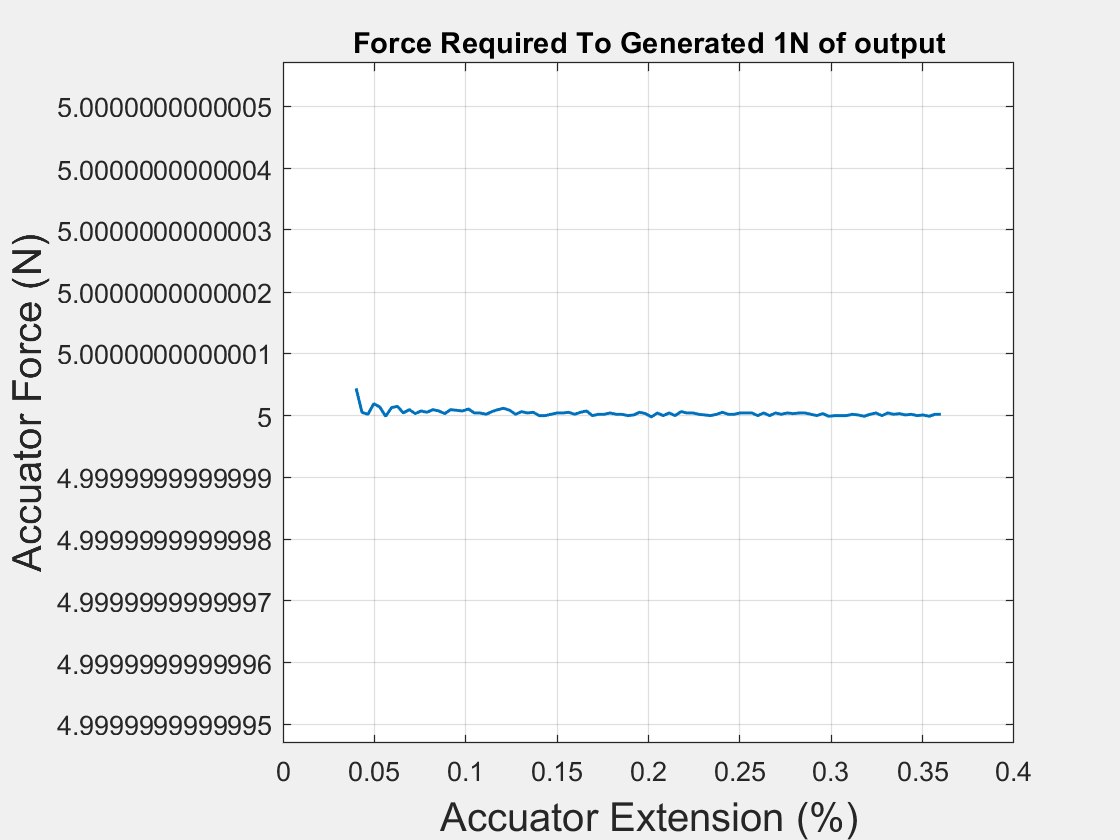


% set up figure 2
figure(2);                       %create new figure
set(2,'WindowStyle','modal')    %dock the figure

plot(accuator,F_acc,'LineWidth',1.1)
grid on
xlabel('Accuator Extension (%)', 'fontsize', 15);
ylabel('Accuator Force (N)', 'fontsize', 15);
title('Force Required To Generated 1N of output');